syms E I q0 L x
E = 210*10^9

E = 2.1000e+11

I = (1/12)*10^(-8)

I = 8.3333e-10

q0 = 100

q0 = 100

L = 0.1

L = 0.1000

F = 40

F = 40

c.

% n = 1
displayFormula("q11 = int(q0*x, x, 0, L)")

$$\frac{1}{2}=\int_{0}^{\frac{1}{10}}100\,x\mathrm{d}x$$

q11 = int(q0*x, x, 0, L)

$$q11 = \frac{1}{2}$$

displayFormula("q12 = int((-q0/L)*x^2 + 2*q0*x^1, x, L, 2*L)")

$$\frac{2}{3}=\int_{\frac{1}{10}}^{\frac{2}{10}}\left(\frac{-100}{\frac{1}{10}}\,x^{2}+2\,100\,x\right)\mathrm{d}x$$

q12 = int((-q0/L)*x^2 + 2*q0*x^1, x, L, 2*L)

$$q12 = \frac{2}{3}$$


q1 = q11 + q12

$$q1 = \frac{7}{6}$$

F1 = q1 - 2*F*L - (7/6)*q0*L^2 + 2*F*L

$$F1 = 0$$




% n = 2
displayFormula("q21 = int(q0*x^2, x, 0, L)")

$$\frac{1}{30}=\int_{0}^{\frac{1}{10}}100\,x^{2}\mathrm{d}x$$

q21 = int(q0*x^2, x, 0, L)

$$q21 = \frac{1}{30}$$

displayFormula("q22 = int((-q0/L)*x^3 + 2*q0*x^2, x, L, 2*L)")

$$\frac{11}{120}=\int_{\frac{1}{10}}^{\frac{2}{10}}\left(\frac{-100}{\frac{1}{10}}\,x^{3}+2\,100\,x^{2}\right)\mathrm{d}x$$

q22 = int((-q0/L)*x^3 + 2*q0*x^2, x, L, 2*L)

$$q22 = \frac{11}{120}$$


q2 = q21 + q22

$$q2 = \frac{1}{8}$$

F2 = q2 - F*(2*L)^2

$$F2 = -\frac{59}{40}$$


A = (E*I) * [0 0; 0 int(4, x, 0, 2*L)]

$$A = \left(\begin{array}{cc} 0 & 0\\ 0 & 140 \end{array}\right)$$

B = [F1; F2]

$$B = \left(\begin{array}{c} 0\\ -\frac{59}{40} \end{array}\right)$$

X = double(linsolve(A, B))

X =          0
   -0.0105





% n = 3
displayFormula("q31 = int(q0*x^3, x, 0, L)")

$$\frac{1}{400}=\int_{0}^{\frac{1}{10}}100\,x^{3}\mathrm{d}x$$

q31 = int(q0*x^3, x, 0, L)

$$q31 = \frac{1}{400}$$

displayFormula("q32 = int((-q0/L)*x^4 + 2*q0*x^3, x, L, 2*L)")

$$\frac{13}{1000}=\int_{\frac{1}{10}}^{\frac{2}{10}}\left(\frac{-100}{\frac{1}{10}}\,x^{4}+2\,100\,x^{3}\right)\mathrm{d}x$$

q32 = int((-q0/L)*x^4 + 2*q0*x^3, x, L, 2*L)

$$q32 = \frac{13}{1000}$$


q3 = q31 + q32

$$q3 = \frac{31}{2000}$$

F3 = q3 - F*(2*L)^3

$$F3 = -\frac{609}{2000}$$


A = (E*I) * [int(4, x, 0, 2*L)      int(12*x, x, 0, 2*L);
             int(12*x, x, 0, 2*L)   int(36*x^2, x, 0, 2*L)]

$$A = \left(\begin{array}{cc} 140 & 42\\ 42 & \frac{84}{5} \end{array}\right)$$

B = [F2; F3]

$$B = \left(\begin{array}{c} -\frac{59}{40}\\ -\frac{609}{2000} \end{array}\right)$$

X = double(linsolve(A,B))

X =    -0.0204
    0.0329





% n = 4
displayFormula("q41 = int(q0*x^4, x, 0, L)")

$$\frac{1}{5000}=\int_{0}^{\frac{1}{10}}100\,x^{4}\mathrm{d}x$$

q41 = int(q0*x^4, x, 0, L)

$$q41 = \frac{1}{5000}$$

displayFormula("q42 = int((-q0/L)*x^5 + 2*q0*x^4, x, L, 2*L)")

$$\frac{19}{10000}=\int_{\frac{1}{10}}^{\frac{2}{10}}\left(\frac{-100}{\frac{1}{10}}\,x^{5}+2\,100\,x^{4}\right)\mathrm{d}x$$

q42 = int((-q0/L)*x^5 + 2*q0*x^4, x, L, 2*L)

$$q42 = \frac{19}{10000}$$


q4 = q41 + q42

$$q4 = \frac{21}{10000}$$

F4 = q4 - F*(2*L)^4

$$F4 = -\frac{619}{10000}$$


A = (E*I) * [int(4, x, 0, 2*L)      int(12*x, x, 0, 2*L)    int(24*x^2, x, 0, 2*L);
             int(12*x, x, 0, 2*L)   int(36*x^2, x, 0, 2*L)  int(72*x^3, x, 0, 2*L);
             int(24*x^2, x, 0, 2*L) int(72*x^3, x, 0, 2*L)  int(144*x^4, x, 0, 2*L)]

$$A = \left(\begin{array}{ccc} 140 & 42 & \frac{56}{5}\\ 42 & \frac{84}{5} & \frac{126}{25}\\ \frac{56}{5} & \frac{126}{25} & \frac{1008}{625} \end{array}\right)$$

B = [F2; F3; F4]

$$B = \left(\begin{array}{c} -\frac{59}{40}\\ -\frac{609}{2000}\\ -\frac{619}{10000} \end{array}\right)$$

X = double(linsolve(A,B))

X =    -0.0196
    0.0248
    0.0201





% n = 5
displayFormula("q51 = int(q0*x^5, x, 0, L)")

$$\frac{1}{60000}=\int_{0}^{\frac{1}{10}}100\,x^{5}\mathrm{d}x$$

q51 = int(q0*x^5, x, 0, L)

$$q51 = \frac{1}{60000}$$

displayFormula("q52 = int((-q0/L)*x^6 + 2*q0*x^5, x, L, 2*L)")

$$\frac{1}{3500}=\int_{\frac{1}{10}}^{\frac{2}{10}}\left(\frac{-100}{\frac{1}{10}}\,x^{6}+2\,100\,x^{5}\right)\mathrm{d}x$$

q52 = int((-q0/L)*x^6 + 2*q0*x^5, x, L, 2*L)

$$q52 = \frac{1}{3500}$$


q5 = q51 + q52

$$q5 = \frac{127}{420000}$$

F5 = q5 - F*(2*L)^5

$$F5 = -\frac{5249}{420000}$$


A = (E*I) * [int(4, x, 0, 2*L)      int(12*x, x, 0, 2*L)     int(24*x^2, x, 0, 2*L)  int(40*x^3, x, 0, 2*L);
             int(12*x, x, 0, 2*L)   int(36*x^2, x, 0, 2*L)   int(72*x^3, x, 0, 2*L)  int(120*x^4, x, 0, 2*L);
             int(24*x^2, x, 0, 2*L) int(72*x^3, x, 0, 2*L)   int(144*x^4, x, 0, 2*L) int(240*x^5, x, 0, 2*L);
             int(40*x^3, x, 0, 2*L) int(120*x^4, x, 0, 2*L)  int(240*x^5, x, 0, 2*L) int(400*x^6, x, 0, 2*L)]

$$A = \left(\begin{array}{cccc} 140 & 42 & \frac{56}{5} & \frac{14}{5}\\ 42 & \frac{84}{5} & \frac{126}{25} & \frac{168}{125}\\ \frac{56}{5} & \frac{126}{25} & \frac{1008}{625} & \frac{56}{125}\\ \frac{14}{5} & \frac{168}{125} & \frac{56}{125} & \frac{16}{125} \end{array}\right)$$

B = [F2; F3; F4; F5]

$$B = \left(\begin{array}{c} -\frac{59}{40}\\ -\frac{609}{2000}\\ -\frac{619}{10000}\\ -\frac{5249}{420000} \end{array}\right)$$

X = double(linsolve(A,B))

X =    -0.0195
    0.0229
    0.0320
   -0.0238


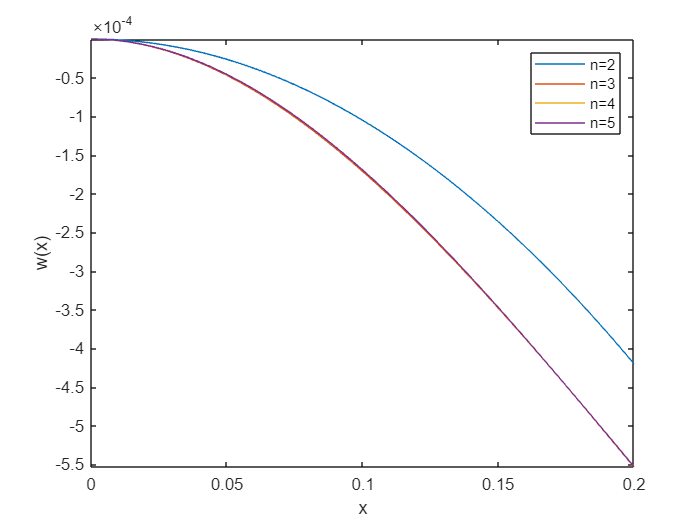




% plotting
fplot((-0.0105)*x^2, [0, 0.2])
hold on
fplot((-0.0204)*x^2 + (0.0329)*x^3, [0, 0.2])
fplot((-0.0196)*x^2 + (0.0248)*x^3 + (0.0201)*x^4, [0, 0.2])
fplot((-0.0195)*x^2 + (0.0229)*x^3 + (0.0320)*x^4 + (-0.0238)*x^5, [0, 0.2])
hold off

xlabel('x')
ylabel('w(x)')
legend('n=2', 'n=3', 'n=4', 'n=5')





% checking derivative
diff(diff(x^2))*diff(diff(x^2))

$$ans = 4$$

diff(diff(x^2))*diff(diff(x^3))

$$ans = 12\,x$$

diff(diff(x^2))*diff(diff(x^4))

$$ans = 24\,x^{2}$$

diff(diff(x^2))*diff(diff(x^5))

$$ans = 40\,x^{3}$$


diff(diff(x^3))*diff(diff(x^2))

$$ans = 12\,x$$

diff(diff(x^3))*diff(diff(x^3))

$$ans = 36\,x^{2}$$

diff(diff(x^3))*diff(diff(x^4))

$$ans = 72\,x^{3}$$

diff(diff(x^3))*diff(diff(x^5))

$$ans = 120\,x^{4}$$


diff(diff(x^4))*diff(diff(x^2))

$$ans = 24\,x^{2}$$

diff(diff(x^4))*diff(diff(x^3))

$$ans = 72\,x^{3}$$

diff(diff(x^4))*diff(diff(x^4))

$$ans = 144\,x^{4}$$

diff(diff(x^4))*diff(diff(x^5))

$$ans = 240\,x^{5}$$


diff(diff(x^5))*diff(diff(x^2))

$$ans = 40\,x^{3}$$

diff(diff(x^5))*diff(diff(x^3))

$$ans = 120\,x^{4}$$

diff(diff(x^5))*diff(diff(x^4))

$$ans = 240\,x^{5}$$

diff(diff(x^5))*diff(diff(x^5))

$$ans = 400\,x^{6}$$

d.

% n = 2
syms a1 a2 u_h
u_h = a1*x + a2*x^2

$$u\_h = a_{2}\,x^{2}+a_{1}\,x$$

I2 = 0.5*E*I*int(diff(diff(u_h))^2, x, 0, 2*L) - int(u_h*q0, x, 0, L) - int(u_h*((-q0/L)*x+2*q0), x, L, 2*L) + F*(a1*2*L+a2*((2*L)^2))

$$I2 = 70\,{a_{2}}^{2}+\frac{59\,a_{2}}{40}+\frac{41\,a_{1}}{6}$$

diff(I2, a2)

$$ans = 140\,a_{2}+\frac{59}{40}$$


% n = 3
syms a1 a2 a3 u_h
u_h = a1*x + a2*x^2 + a3*x^3

$$u\_h = a_{3}\,x^{3}+a_{2}\,x^{2}+a_{1}\,x$$

I3 = 0.5*E*I*int(diff(diff(u_h))^2, x, 0, 2*L) - int(u_h*q0, x, 0, L) - int(u_h*((-q0/L)*x+2*q0), x, L, 2*L) + F*(a1*2*L + a2*((2*L)^2) + a3*((2*L)^3))

$$I3 = 70\,{a_{2}}^{2}+42\,a_{2}\,a_{3}+\frac{59\,a_{2}}{40}+\frac{42\,{a_{3}}^{2}}{5}+\frac{609\,a_{3}}{2000}+\frac{41\,a_{1}}{6}$$

diff(I3, a2)

$$ans = 140\,a_{2}+42\,a_{3}+\frac{59}{40}$$

diff(I3, a3)

$$ans = 42\,a_{2}+\frac{84\,a_{3}}{5}+\frac{609}{2000}$$


A = [140 42; 42 84/5]

A =   140.0000   42.0000
   42.0000   16.8000


B = [-59/40; -609/2000]

B =    -1.4750
   -0.3045


X = double(linsolve(A,B))

X =    -0.0204
    0.0329



% n = 4
syms a1 a2 a3 a4 u_h
u_h = a1*x + a2*x^2 + a3*x^3 + a4*x^4

$$u\_h = a_{4}\,x^{4}+a_{3}\,x^{3}+a_{2}\,x^{2}+a_{1}\,x$$

I4 = 0.5*E*I*int(diff(diff(u_h))^2, x, 0, 2*L) - int(u_h*q0, x, 0, L) - int(u_h*((-q0/L)*x+2*q0), x, L, 2*L) + F*(a1*2*L + a2*((2*L)^2) + a3*((2*L)^3) + a4*((2*L)^4))

$$I4 = 70\,{a_{2}}^{2}+42\,a_{2}\,a_{3}+\frac{56\,a_{2}\,a_{4}}{5}+\frac{59\,a_{2}}{40}+\frac{42\,{a_{3}}^{2}}{5}+\frac{126\,a_{3}\,a_{4}}{25}+\frac{609\,a_{3}}{2000}+\frac{504\,{a_{4}}^{2}}{625}+\frac{619\,a_{4}}{10000}+\frac{41\,a_{1}}{6}$$

diff(I4, a2)

$$ans = 140\,a_{2}+42\,a_{3}+\frac{56\,a_{4}}{5}+\frac{59}{40}$$

diff(I4, a3)

$$ans = 42\,a_{2}+\frac{84\,a_{3}}{5}+\frac{126\,a_{4}}{25}+\frac{609}{2000}$$

diff(I4, a4)

$$ans = \frac{56\,a_{2}}{5}+\frac{126\,a_{3}}{25}+\frac{1008\,a_{4}}{625}+\frac{619}{10000}$$


A = [140 42 56/5; 42 84/5 126/25; 56/5 126/25 1008/625]

A =   140.0000   42.0000   11.2000
   42.0000   16.8000    5.0400
   11.2000    5.0400    1.6128


B = [-59/40; -609/2000; -619/10000]

B =    -1.4750
   -0.3045
   -0.0619


X = double(linsolve(A,B))

X =    -0.0196
    0.0248
    0.0201



% n = 5
syms a1 a2 a3 a4 a5 u_h
u_h = a1*x + a2*x^2 + a3*x^3 + a4*x^4 + a5*x^5

$$u\_h = a_{5}\,x^{5}+a_{4}\,x^{4}+a_{3}\,x^{3}+a_{2}\,x^{2}+a_{1}\,x$$

I5 = 0.5*E*I*int(diff(diff(u_h))^2, x, 0, 2*L) - int(u_h*q0, x, 0, L) - int(u_h*((-q0/L)*x+2*q0), x, L, 2*L) + F*(a1*2*L + a2*((2*L)^2) + a3*((2*L)^3) + a4*((2*L)^4) + a5*((2*L)^5))

$$I5 = 70\,{a_{2}}^{2}+42\,a_{2}\,a_{3}+\frac{56\,a_{2}\,a_{4}}{5}+\frac{14\,a_{2}\,a_{5}}{5}+\frac{59\,a_{2}}{40}+\frac{42\,{a_{3}}^{2}}{5}+\frac{126\,a_{3}\,a_{4}}{25}+\frac{168\,a_{3}\,a_{5}}{125}+\frac{609\,a_{3}}{2000}+\frac{504\,{a_{4}}^{2}}{625}+\frac{56\,a_{4}\,a_{5}}{125}+\frac{619\,a_{4}}{10000}+\frac{8\,{a_{5}}^{2}}{125}+\frac{5249\,a_{5}}{420000}+\frac{41\,a_{1}}{6}$$

diff(I5, a2)

$$ans = 140\,a_{2}+42\,a_{3}+\frac{56\,a_{4}}{5}+\frac{14\,a_{5}}{5}+\frac{59}{40}$$

diff(I5, a3)

$$ans = 42\,a_{2}+\frac{84\,a_{3}}{5}+\frac{126\,a_{4}}{25}+\frac{168\,a_{5}}{125}+\frac{609}{2000}$$

diff(I5, a4)

$$ans = \frac{56\,a_{2}}{5}+\frac{126\,a_{3}}{25}+\frac{1008\,a_{4}}{625}+\frac{56\,a_{5}}{125}+\frac{619}{10000}$$

diff(I5, a5)

$$ans = \frac{14\,a_{2}}{5}+\frac{168\,a_{3}}{125}+\frac{56\,a_{4}}{125}+\frac{16\,a_{5}}{125}+\frac{5249}{420000}$$


A = [140 42 56/5 14/5; 42 84/5 126/25 168/125; 56/5 126/25 1008/625 56/125; 14/5 168/125 56/125 16/125]

A =   140.0000   42.0000   11.2000    2.8000
   42.0000   16.8000    5.0400    1.3440
   11.2000    5.0400    1.6128    0.4480
    2.8000    1.3440    0.4480    0.1280


B = [-59/40; -609/2000; -619/10000; -5249/420000]

B =    -1.4750
   -0.3045
   -0.0619
   -0.0125


X = double(linsolve(A,B))

X =    -0.0195
    0.0229
    0.0320
   -0.0238


f.

syms u2 u3 u4 u5
u2 = -0.0105*x^2

$$u2 = -\frac{21\,x^{2}}{2000}$$

u3 = -0.0204*x^2 + 0.0329*x^3

$$u3 = \frac{329\,x^{3}}{10000}-\frac{51\,x^{2}}{2500}$$

u4 = -0.0196*x^2 + 0.0248*x^3 + 0.0201*x^4

$$u4 = \frac{201\,x^{4}}{10000}+\frac{31\,x^{3}}{1250}-\frac{49\,x^{2}}{2500}$$

u5 = -0.0195*x^2 + 0.0229*x^3 + 0.0320*x^4 - 0.0238*x^5

$$u5 = -\frac{119\,x^{5}}{5000}+\frac{4\,x^{4}}{125}+\frac{229\,x^{3}}{10000}-\frac{39\,x^{2}}{2000}$$


% n=2
u25 = u2 - u5

$$u25 = \frac{119\,x^{5}}{5000}-\frac{4\,x^{4}}{125}-\frac{229\,x^{3}}{10000}+\frac{9\,x^{2}}{1000}$$

I25 = double(0.5*E*I*int(diff(diff(u25))^2, x, 0, 2*L) - int(u25*q0, x, 0, L) - int(u25*((-q0/L)*x+2*q0), x, L, 2*L) + F*((-0.0105*(2*L)^2) - (-0.0195*(2*L)^2 + 0.0229*(2*L)^3 + 0.0320*(2*L)^4 - 0.0238*(2*L)^5)))

I25 = 0.0069


% n=3
u35 = u3 - u5

$$u35 = \frac{119\,x^{5}}{5000}-\frac{4\,x^{4}}{125}+\frac{x^{3}}{100}-\frac{9\,x^{2}}{10000}$$

I35 = double(0.5*E*I*int(diff(diff(u35))^2, x, 0, 2*L) - int(u35*q0, x, 0, L) - int(u35*((-q0/L)*x+2*q0), x, L, 2*L) + F*((-0.0204*(2*L)^2 + 0.0329*(2*L)^3) - (-0.0195*(2*L)^2 + 0.0229*(2*L)^3 + 0.0320*(2*L)^4 - 0.0238*(2*L)^5)))

I35 = 4.3308e-05


% n=4
u45 = u4 - u5

$$u45 = \frac{119\,x^{5}}{5000}-\frac{119\,x^{4}}{10000}+\frac{19\,x^{3}}{10000}-\frac{x^{2}}{10000}$$

I45 = double(0.5*E*I*int(diff(diff(u45))^2, x, 0, 2*L) - int(u45*q0, x, 0, L) - int(u45*((-q0/L)*x+2*q0), x, L, 2*L) + F*((-0.0196*(2*L)^2 + 0.0248*(2*L)^3 + 0.0201*(2*L)^4) - (-0.0195*(2*L)^2 + 0.0229*(2*L)^3 + 0.0320*(2*L)^4 - 0.0238*(2*L)^5)))

I45 = -8.0235e-06